% Initialization
close all; clear; clc;

% Symbolic variables
syms mu sigma t f w real

% Symbolic Gaussian function
x=1/sqrt(2*pi*sigma^2)*exp(-1/2*((t-mu)/sigma)^2)

$$x = \frac{\sqrt{2}\,{\mathrm{e}}^{-\frac{{\left(\mu -t\right)}^{2}}{2\,\sigma^{2}}}}{2\,\sqrt{\pi }\,\sqrt{\sigma^{2}}}$$


% Symbolic Fourier transform
y=fourier(x,'t','w')

$$y = \frac{\sqrt{2}\,{\mathrm{e}}^{-\frac{\sigma^{2}\,{\left(w+\frac{\mu \,\mathrm{i}}{\sigma^{2}}\right)}^{2}}{2}-\frac{\mu^{2}}{2\,\sigma^{2}}}}{2\,\sqrt{\frac{1}{2\,\sigma^{2}}}\,\sqrt{\sigma^{2}}}$$

y=simplify(subs(y,w,2*pi*f))

$$y = {\mathrm{e}}^{-2\,\pi \,f\,\left(f\,\pi \,\sigma^{2}+\mu \,\mathrm{i}\right)}$$

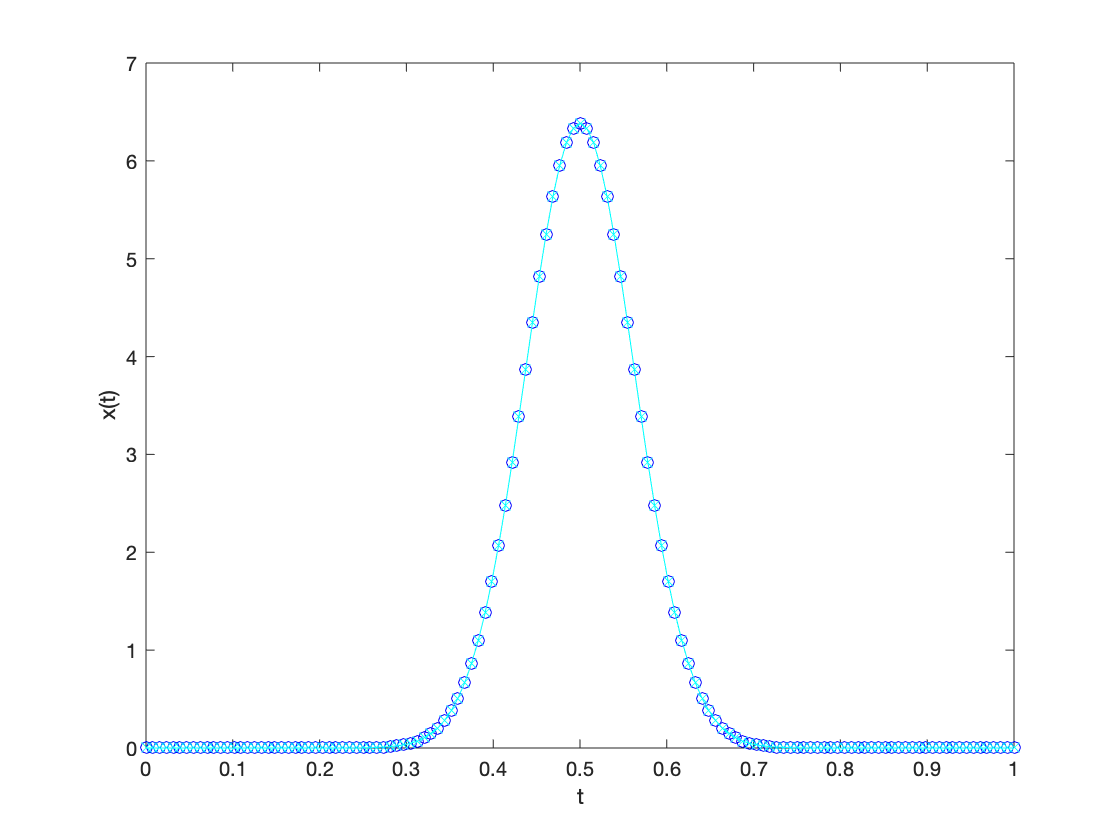


% Numerical values
mu=1/2;
sigma=2^-4;
dt=2^-7;
t=0:dt:1;

% Numerical Gaussian function
xn=eval(x);

% Numerical Fourier transform
[f,yn]=computeFFT_NEW(t,xn);

% Solution in the time domain
figure;
plot(t,xn,'b-o');
hold on
plot(t,eval(x),'c-x')
xlabel('t'); ylabel('x(t)');

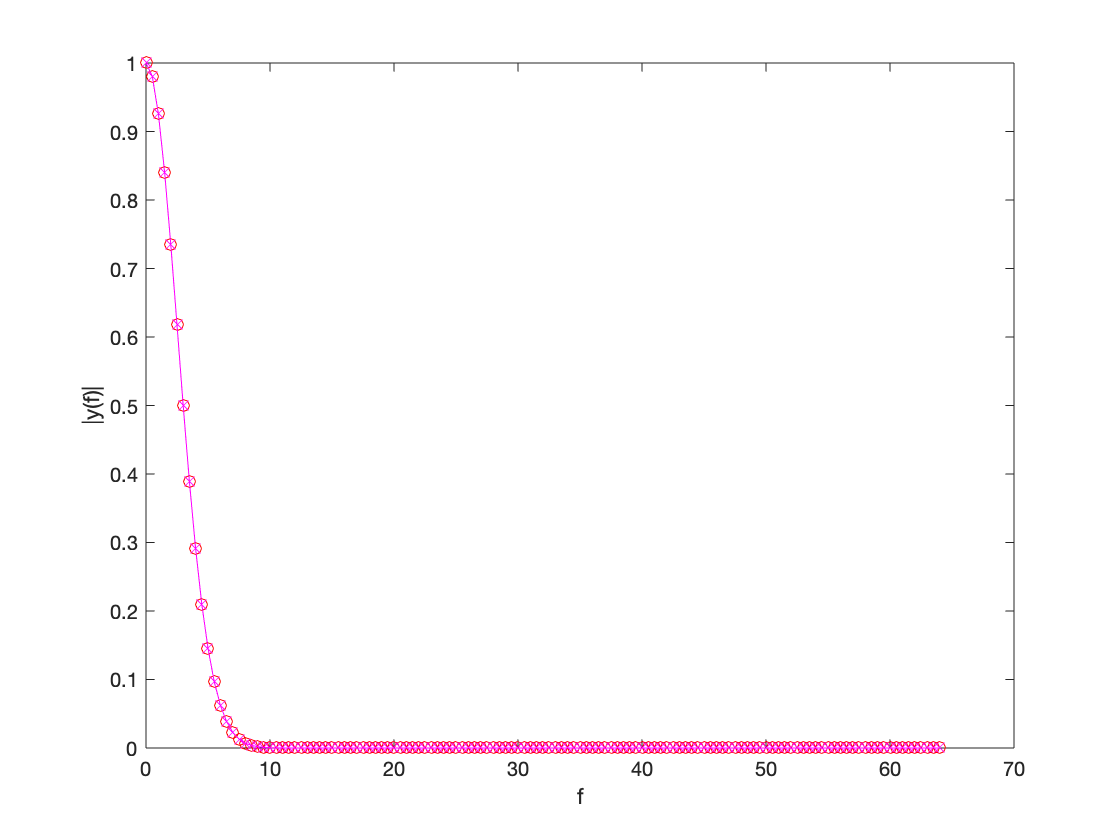


% Solution in the frequency domain
figure;
plot(f,abs(yn),'r-o');
hold on
plot(f,abs(eval(y)),'m-x');
xlabel('f'); ylabel('|y(f)|');


% Scaling factor (hopefully 1)
a=abs(yn); b=abs(eval(y)); fac=b(1)/a(1)

fac = 1.0000